# Izhikevich spiking model for cortical neurons

## Objectives

This [live script](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html) is an attempt to reproduce the neuronal dynamics of most cortical neurons by using the Izhikevich model of spiking neurons. It is biologically as plausible as the [Hodgkin-Huxley model](https://en.wikipedia.org/wiki/Hodgkin%E2%80%93Huxley_model), yet computationally viable like the integrate-and-fire models. For more information, please see the [original paper](http://www.izhikevich.org/publications/spikes.pdf) of Eugene Izhikevich [*IEEE Trans on Neural Networks, 14(6), 2003*] as well as his book, [Dynamical Systems in Neuroscience](https://www.izhikevich.org/publications/dsn.pdf). In this Live Script, the differential equations defining the Izhikevich model have been solved both with a for loop using the forward Euler method, as well as using the [MATLAB in-built ode solver](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html). One of the two approaches can be selected using a drop down menu.

This Live Script is [accompanied by an App](matlab:open('./IzhikevichApp.mlapp')) which only uses the for-loop method.  

## 1 The spiking model

### 1.1 Spiking model equation of Izhikevich

The spiking model of cortical neurons is based on the following equations

$C\dot{v} =k\;\left(v-v_r \right)\left(v-v_t \right)-u+I$....................[1]

$\dot{u} =a\left\lbrace b\left(v-v_r \right)-u\right\rbrace$...................................[2] 

$\textrm{If}\;v\ge v_{\textrm{peak}} ,\textrm{then}$$v=c,u=u+d$.................[3]

*From: Eugene M. Izhikevich (2007). Dynamical systems in neuroscience: the geometry of excitability and bursting (MIT Press).   pp. 273*

where $\mathit{\mathbf{v}}$ is the membrane potential, $\mathit{\mathbf{C}}$ is the membrane capacitance and $\mathit{\mathbf{u}}$ is the membrane recovery variable. ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{r}}}$ is the resting membrane potential and ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{t}}}$ is the instantaneous spiking threshold. A large diversity of cortical neurons can be simulated by setting the membrane parameters $\mathit{\mathbf{a}}$, $\mathit{\mathbf{b}}$, $\mathit{\mathbf{c}}$ & $\mathit{\mathbf{d}}$ appropriately (see figure below). 

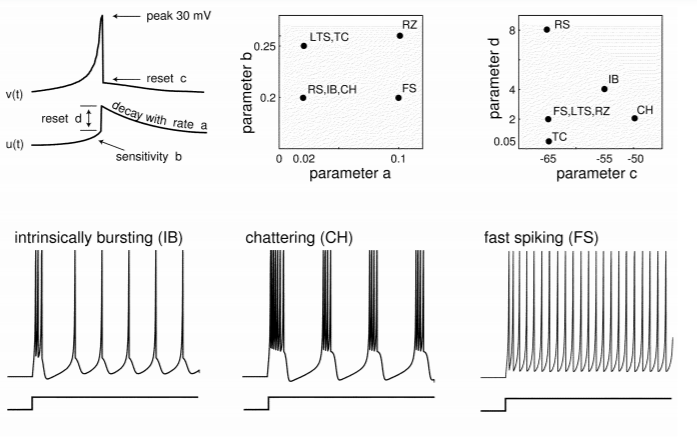

*From: Eugene M. Izhikevich (2003). Simple Model of Spiking Neurons, IEEE Transactions on Neural networks, 14(6).  *

### 1.2 The parameters of the model

Here the parameters of the model, both for membrane as well as stimulus properties are defined.

#### 1.2.1 Membrane parameters

The four parameters of the model $\mathit{\mathbf{a}}$, $\mathit{\mathbf{b}}$, $\mathit{\mathbf{c}}$ & $\mathit{\mathbf{d}}$ control various membrane properties and affect spiking behavior. They are

- $\mathit{\mathbf{a}}$ = recovery time constant

- $\mathit{\mathbf{b}}$ = determines whether recovery variable, $\mathit{\mathbf{u}}$, is an amplifying ($\mathit{\mathbf{b}}$ < 0) or a resonant ($\mathit{\mathbf{b}}$ > 0) variable.

- $\mathit{\mathbf{c}}$ = voltage reset value following spiking

- $\mathit{\mathbf{d}}$ = total amount of outward - inward current during spiking (affects after spiking behaviour)

% Define stimulus and...
params.stm.I          = 70;                         % stimulation amplitude (current)
params.stm.dt         = 0;
params.stm.T          = 1000;                       % total time of stimulation (ms)
params.stm.t          = 1;                          % time step of stimulation (ms)
params.stm.pulseWidth = 0.9;  % width of stimulation pulse (fraction of total time)
params.stm.dt         = params.stm.T*(1 - params.stm.pulseWidth);

% ...membrane parameters
params.mem.C  = 170;          % membrane capacitance
params.mem.k  = 0.7;
params.mem.vr = -60;        % resting membrane potential
params.mem.vt = -52;          % instantaneous threshold potential
params.mem.a  = 0.09;        % recovery time constant
params.mem.b  = -3.4;        % determines whether u is amplifying (b<0) or resonant(b>0)
params.mem.vpeak = 41;        % spike cutoff
params.mem.c  = -50;        % voltage reset value
params.mem.d  = 170;          % total outward-inward current during spike

## 2. Results

We will now solve the differential equations defining the Izhikevich model using either one of two approaches

- The two equations shown above are used to simulate the model according to the forward Euler method. If spiking occurs, membrane potential $\mathit{\mathbf{v}}$ is reset to voltage reset value $\mathit{\mathbf{c}}$ and recovery variable $\mathit{\mathbf{u}}\;$is updated

- The differential equations are solved using the in-built MATLAB ode solver. 

Set up options for simulating the Izhikevich model

option = 2; % 1: for loop | 2: ODE solver

### 2.1 Option1: Simulate the model in a for loop

if option == 1
    % initialize/calculate some parameters
    n = round(params.stm.T/params.stm.t); % simulation time steps
    I = [zeros(1,int32((1-params.stm.pulseWidth)*n)),...
        params.stm.I*ones(1,int32(params.stm.pulseWidth*n))]; % DC current
    v = params.mem.vr*ones(1,n); u = 0*v; % initial values for membrane potential & recovery
    
    % simulate the model
    for i = 1:n-1
        v(i+1)=v(i)+params.stm.t*(0.7*(v(i)-params.mem.vr)*(v(i)-params.mem.vt)-u(i)+I(i))/params.mem.C;  % membrane potential
        u(i+1)=u(i)+params.stm.t*params.mem.a*(params.mem.b*(v(i)-params.mem.vr)-u(i));                   % membrane rec variable
        
        % if spike occurs, reset membrane potential and recovery variable
        if v(i+1)>=params.mem.vpeak
            v(i)= params.mem.vpeak;
            v(i+1)=params.mem.c;
            u(i+1)=u(i+1)+params.mem.d;
        end
    end
    output = v;
    
    % plot the simulation
    plotIzhikevichSimulation(output,params.stm.t*(1:n),I,params.mem.vr,params.mem.vt)
end

### 2.2 Option 2: Use the in-built ODE solver in MATLAB. 

Set up the equations for using MATLAB symbolic toolbox

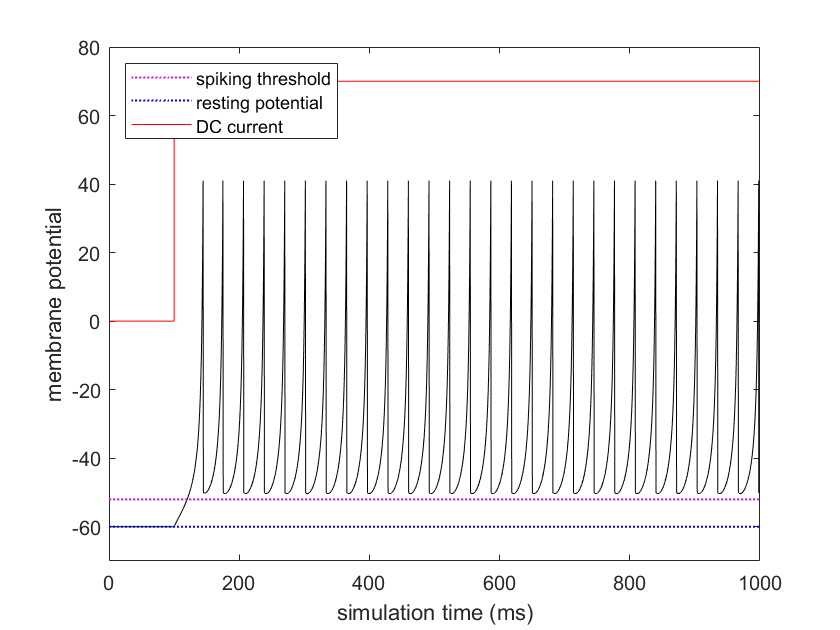

if option == 2
    clearvars -except params option
    syms v(t) u(t) C k vr vt I a b vpeak c d dt Y
    % Define first derivatives for u and v
    DvDt      = diff(v);
    DuDt      = diff(u);
    % Set up differential equations for u and v
    DE_v      = C*DvDt == k*(v - vr)*(v - vt) - u + I*heaviside(t - dt);
    DE_u      =   DuDt == a*(b*(v - vr) - u);
    % Convert the DE to a vector field
    [DE_VF,~] = odeToVectorField(DE_v,DE_u);

At this point we are moving from symbolic to the numeric representations:

    % ...and then, convert to a MATLAB function so we can integrate numerically
    DE = matlabFunction(DE_VF,'vars',{t,Y,[C k vr vt a b vpeak c d I dt]});
    % Set the simulation time and initial conditions
    tspan = [0, params.stm.T];
    IC    = [0, params.mem.vr];
    tout  = tspan(1);
    yout  = IC;
    % ...and define the events function. This events function will help us keep
    % track of the resets in the spiking model
    options = odeset('Events',@events);
    
    ie = 1;            % ie == 1 --> detect v >= vpeak, or, v - vpeak >= 0
    while (ie ~= 2)    % ie == 2 --> detect tsim = T, or, tsim - T = 0
        [t,sol,~,~,ie] = ode45(DE,tspan,IC,options,[cell2mat(struct2cell(params.mem))',cell2mat(struct2cell(params.stm))']);
        
        tout  = [tout;   t(2:end)  ]; %#ok<*AGROW>
        yout  = [yout; sol(2:end,:)];
        
        tspan = [tout(end), params.stm.T];             % adjust the simulation time
        IC    = [IC(2) + params.mem.d, params.mem.c];  % and set the values for v and u according to the spiking model
    end
    output = yout(:,2);
    
    % plot the simulation
    figure;
    Iout = zeros(size(tout));
    Iout(tout>=(1-params.stm.pulseWidth)*max(tout))=params.stm.I;
    plotIzhikevichSimulation(output,tout,Iout,params.mem.vr,params.mem.vt)
end

## Appendix

Function for resetting values using the ODE solver when spikes occur. We use the events function to automatically detect zero crossings during integration. There are two different events we need to track, one for the Spiking model itself $(v \geq v_{peak})$, and one to stop the integration at $t=T$.

function [value,isterminal,direction] = events(t,y,pars)
vpeak      = pars(7);                % Back out the parameters for better readability 
T          = pars(12);
value      = [y(2) - vpeak; T - t];  % And then define the zeros that we need to detected

isterminal = [1;1];   % Stop the integration when zero is detected
direction  = [1;0];   % [Detect only zeros for increasing values; Detect all zeros]
end

Function for plotting the simulation


function plotIzhikevichSimulation(v,t,I,vr,vt)
% inputs: 
% v = simulated membrane potential
% t = time steps of simulation
% I = stimulation current pulse
% vr = resting membrane potential
% vt = instantaneous threshold potential
%-----------------------------------------------------------------
% plot the results
plot(t,v,'k'); hold on  % plot the membrane potential
cp = plot(t,I,'r');     % plot the stimulus pulse
% show resting membrane potential and spiking threshold on the figure
vrl = line([0 max(t)],[vr vr],'color','b','LineStyle',':','LineWidth',1);
vtl = line([0 max(t)],[vt vt],'color','m','LineStyle',':','LineWidth',1);
% plot aesthetics
ylim([vr-10 max(I)+10])
legend([vtl,vrl,cp],{'spiking threshold','resting potential','DC current'},"Location","northwest")
hold off
xlabel('simulation time (ms)')
ylabel('membrane potential')
end

*Copyright 2020 The MathWorks, Inc*